# **MRI Reconstruction Using Deep Learning with U-Net**

MRI reconstruction using deep learning, particularly with U-Net architectures, has shown significant promise in enhancing image quality and reducing scan times. Here are a few important points about this approach:

#### U-Net Architecture:

- Structure: [U-Net](https://www.mathworks.com/help/vision/ref/unet.html) is a convolutional neural network (CNN) designed for image segmentation. It consists of a contracting path to capture context and an expansive path for precise localization.

- Modifications for MRI: The U-Net architecture has been adapted to handle complex-valued MRI data by treating the real and imaginary parts as separate channels.

#### Handling k-Space Data:

- Input: The network can take undersampled k-space data as input, which is the raw frequency domain data acquired during MRI scans.

- Undersampling: Techniques like variable density Poisson disc sampling (VD-PDS) can be used to create masks that undersample the k-space data, reducing acquisition time. Here one can use 1D undersampling in phase encoding direction too.

**Coil Sensitivity Maps:**

Coil sensitivity maps are generated by dividing the absolute value of each coil's image by the RSS image. This normalization step accounts for the varying sensitivity of each coil, producing maps that represent the relative sensitivity of each coil at different spatial locations.

                                                                                                                

         where ***I****c*,*s * is the image from the *c*-th coil and *s*-th slice, and *ϵ* is a small constant to avoid division by zero.

#### Training and Reconstruction:

- Training: The U-Net is trained end-to-end to map undersampled k-space data to fully reconstructed images. The training process involves learning the parameters that best reconstruct the images from the undersampled data.

- Reconstruction: During inference, the trained U-Net model reconstructs high-quality images from new undersampled k-space data, leveraging the learned features and patterns.

dataDir = fullfile(pwd, "data", "inputData");
gtDataDir = fullfile(pwd, "result", "ifftResult");
outDir = fullfile(pwd, "result", "DLResult");

% Get list of input and ground truth files
inputFileList = dir(fullfile(dataDir, '*.h5'));
groundTruthFileList = dir(fullfile(gtDataDir, '*.mat'));

% Split the data into training and testing sets
trainIndices = 1:2;
testIndices = 3;

% Initialize cell arrays for input and ground truth volumes
inputVolumesTrain = cell(1, numel(trainIndices));
groundTruthVolumesTrain = cell(1, numel(trainIndices));
inputVolumesTest = cell(1, numel(testIndices));
groundTruthVolumesTest = cell(1, numel(testIndices));

% Load and undersample input data for training
for i = 1:numel(trainIndices)
    filePath = fullfile(dataDir, inputFileList(trainIndices(i)).name);
    [undersampled_kspace, coilSensitivityMaps] = undersampleKspace(filePath, 0.2); % Adjust density as needed
    inputVolumesTrain{i} = abs(undersampled_kspace);
end

% Concatenate input data along the fourth dimension for training
inputDataTrain = cat(4, inputVolumesTrain{:});

% Load ground truth data for training
for i = 1:numel(trainIndices)
    data = load(fullfile(gtDataDir, groundTruthFileList(trainIndices(i)).name));
    groundTruthVolumesTrain{i} = data.reconImage;
end

% Concatenate ground truth data along the fourth dimension for training
groundTruthDataTrain = cat(4, groundTruthVolumesTrain{:});

% Load and undersample input data for testing
for i = 1:numel(testIndices)
    filePath = fullfile(dataDir, inputFileList(testIndices(i)).name);
    [undersampled_kspace, coilSensitivityMaps] = undersampleKspace(filePath, 0.2); % Adjust density as needed
    inputVolumesTest{i} = abs(undersampled_kspace);
end

% Concatenate input data along the fourth dimension for testing
inputDataTest = cat(4, inputVolumesTest{:});

% Load ground truth data for testing
for i = 1:numel(testIndices)
    data = load(fullfile(gtDataDir, groundTruthFileList(testIndices(i)).name));
    groundTruthVolumesTest{i} = data.reconImage;
end

% Concatenate ground truth data along the fourth dimension for testing
groundTruthDataTest = cat(4, groundTruthVolumesTest{:});


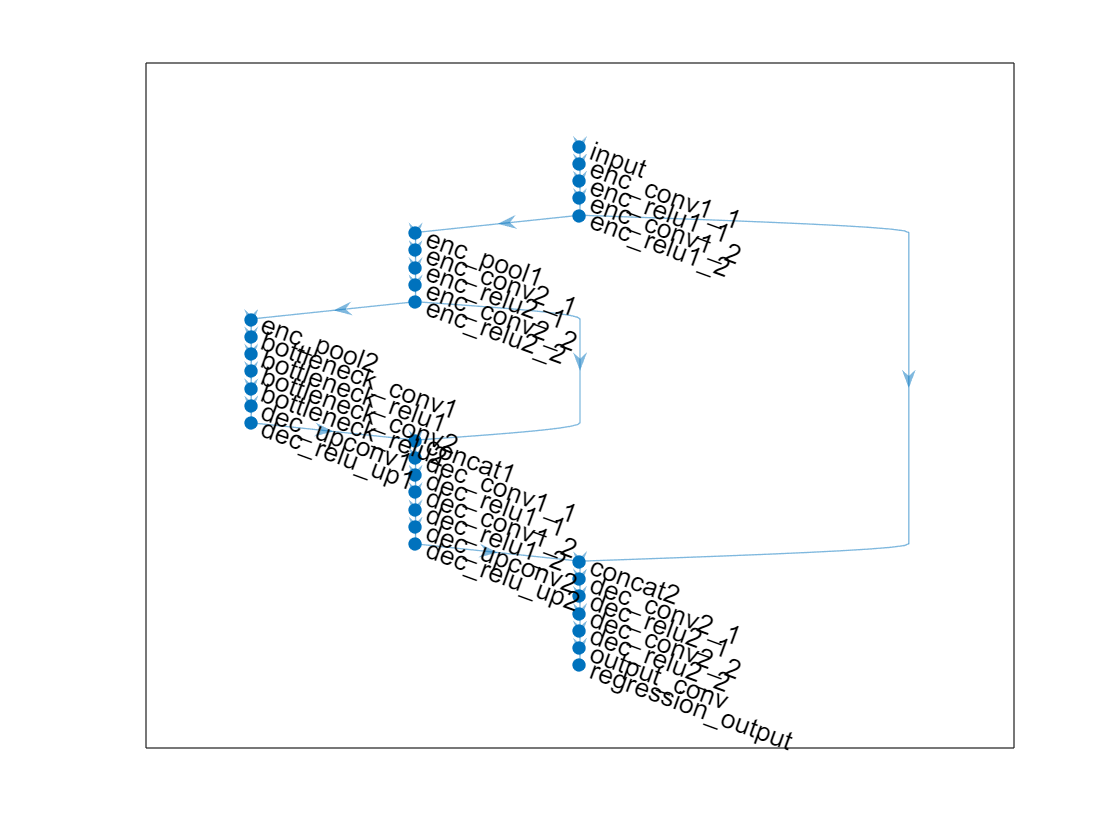


% Define the network layers
layers = [
    % Input layer
    imageInputLayer([256 256 18], 'Name', 'input')

    % Encoder
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'enc_conv1_1')
    reluLayer('Name', 'enc_relu1_1')
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'enc_conv1_2')
    reluLayer('Name', 'enc_relu1_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'enc_pool1')

    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'enc_conv2_1')
    reluLayer('Name', 'enc_relu2_1')
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'enc_conv2_2')
    reluLayer('Name', 'enc_relu2_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'enc_pool2')

    % Bottleneck
    convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'bottleneck_conv1')
    reluLayer('Name', 'bottleneck_relu1')
    convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'bottleneck_conv2')
    reluLayer('Name', 'bottleneck_relu2')

    % Decoder
    transposedConv2dLayer(2, 128, 'Stride', 2, 'Name', 'dec_upconv1')
    reluLayer('Name', 'dec_relu_up1')
    depthConcatenationLayer(2, 'Name', 'concat1')
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'dec_conv1_1')
    reluLayer('Name', 'dec_relu1_1')
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'dec_conv1_2')
    reluLayer('Name', 'dec_relu1_2')

    transposedConv2dLayer(2, 64, 'Stride', 2, 'Name', 'dec_upconv2')
    reluLayer('Name', 'dec_relu_up2')
    depthConcatenationLayer(2, 'Name', 'concat2')
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'dec_conv2_1')
    reluLayer('Name', 'dec_relu2_1')
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'dec_conv2_2')
    reluLayer('Name', 'dec_relu2_2')

    % Output layer for regression
    convolution2dLayer(1, 18, 'Padding', 'same', 'Name', 'output_conv')
    regressionLayer('Name', 'regression_output')
];

% Create layer graph
lgraph = layerGraph(layers);

% Connect skip connections
lgraph = connectLayers(lgraph, 'enc_relu2_2', 'concat1/in2');
lgraph = connectLayers(lgraph, 'enc_relu1_2', 'concat2/in2');


% Plot the layer graph
plot(lgraph);

### Option to add image Augmentation 


% Define augmentation options
% augmenter = imageDataAugmenter( ...
%     'RandRotation', [-10, 10], ...
%     'RandXTranslation', [-5, 5], ...
%     'RandYTranslation', [-5, 5], ...
%     'RandXScale', [0.9, 1.1], ...
%     'RandYScale', [0.9, 1.1]);
% 
% % Create augmented image datastores
% augmentedInputData = augmentedImageDatastore([256 256 18], inputData, ...
%     'DataAugmentation', augmenter);
% 
% % Rename the variable in the ground truth datastore to avoid conflicts
% augmentedGroundTruthData = augmentedImageDatastore([256 256 18], groundTruthData, ...
%     'DataAugmentation', augmenter);
% 
% % Transform the ground truth datastore to rename the variable
% augmentedGroundTruthData = transform(augmentedGroundTruthData, ...
%     @(data) renamevars(data, "input", "response"));


% Define training options
options = trainingOptions("adam", ...
    'MaxEpochs', 600, ...
    'InitialLearnRate', 0.001, ... % Adjust the learning rate
    'L2Regularization', 0.01, ...
    'MiniBatchSize', 12, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'parallel', ...
    'Verbose', true);


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.


Training across multiple GPUs.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       124.12 |       7702.9 |          0.0010 |
|      50 |          50 |       00:00:09 |        33.42 |        558.5 |          0.0010 |
|     100 |         100 |       00:00:17 |        24.87 |        309.4 |          0.0010 |
|     150 |         150 |       00:00:26 |        21.34 |        227.7 |          0.0010 |
|     200 |         200 |       00:00:34 |        19.43 |        188.7 |          0.0010 |
|     250 |         250 |       00:00:42 |        18.70 |        174.9 |          0.0010 |
|     300 |         


% Train the network
net = trainNetwork(inputDataTrain,groundTruthDataTrain, lgraph, options);


# Quantitative Measure (SSIM and PSNR)

### SSIM (Structural Similarity Index)

The Structural Similarity Index ([SSIM](https://www.mathworks.com/help/releases/R2024b/images/ref/ssim.html)) is a metric used to measure the similarity between two images. It considers changes in structural information, luminance, and contrast to provide a more perceptually accurate assessment of image quality compared to traditional methods. SSIM values range from -1 to 1, where 1 indicates perfect similarity.

### PSNR (Peak Signal-to-Noise Ratio)

Peak Signal-to-Noise Ratio ([PSNR](https://www.mathworks.com/help/releases/R2024b/vision/ref/psnr.html?browser=F1help)) is a metric used to evaluate the quality of a reconstructed or compressed image compared to the original. It is calculated using the mean squared error (MSE) between the two images. PSNR is expressed in decibels (dB), with higher values indicating better image quality. Typically, a PSNR value above 30 dB is considered good quality.

result = predict(net,inputDataTest);

Reconstructed MR Image PSNR 36.9479

psnrRes =psnr(result,single(groundTruthDataTest));

Reconstructed MR Image SSIM 0.9256

ans = single
0.9256

ssimRes =ssim(result,single(groundTruthDataTest));
fprintf('Reconstructed MR Image PSNR %.4f', psnrRes);
fprintf('Reconstructed MR Image SSIM %.4f', ssimRes);

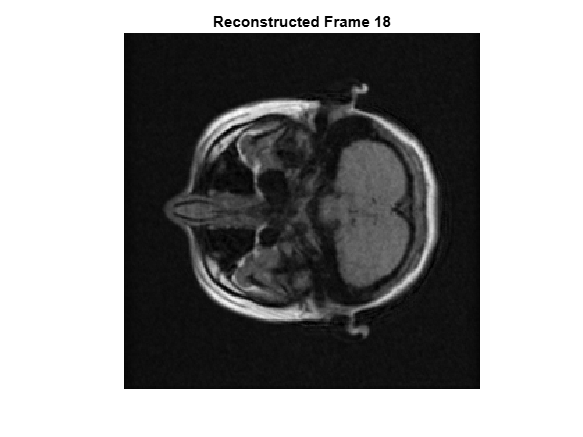

figure;
for frame = 1:18
    imshow(abs(result(:,:,frame)), []);

    title(sprintf('Reconstructed Frame %d', frame));
    pause(0.5); % Pause for visualization
end

# Visualization of MRI Reconstruction

Visualizing MRI reconstruction results is crucial for analyzing and interpreting the data. Various visualization techniques can be employed to view and understand the reconstructed images effectively.

**Medical volume datastore **

The [`medicalVolume`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.html) function in MATLAB is used to create a medical volume object from image data. This object encapsulates the voxel data and associated metadata, such as the volume's geometry and patient coordinate system

R = medicalref3d(size(result));
medVolDLReconImage =medicalVolume(result,R);
medVolDLReconImage.VolumeGeometry.PatientCoordinateSystem ="LPS+";
voxInfo =medVolDLReconImage.Voxels;
min_val = min(voxInfo(:));
max_val = max(voxInfo(:));
normalized_data = (voxInfo(:) - min_val) / (max_val - min_val);

data =reshape(normalized_data,[256 256 18]);
newMedVol= medicalVolume(data,medVolDLReconImage.VolumeGeometry);

## Visualization Methods

#### Slice View:

Displays individual slices of the 3D reconstructed image, allowing detailed examination of each slice.

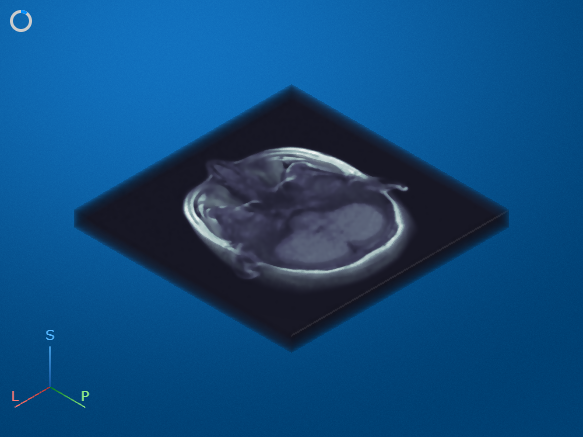

sliceViewer(newMedVol,Parent=figure)

### Volume Rendering

Provides a 3D visualization of the reconstructed image using cinematic rendering, enhancing the depth and detail of the image.

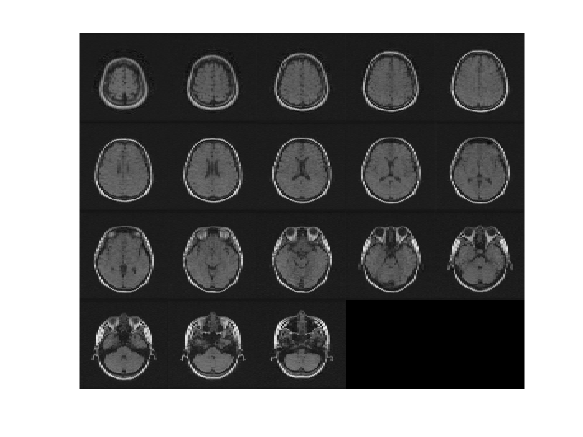

c =bone(20);
volshow(newMedVol,RenderingStyle="CinematicRendering",Colormap=c)

### Montage View

Creates a montage of slices from the 3D reconstructed image, offering a comprehensive overview of the entire volume.

montage(newMedVol)


% Function to generate VD-PDS mask
function samplingMask = generatePoissonDiscMask(m, n, density)
    % Create a radial density profile
    [X, Y] = meshgrid(linspace(-1, 1, n), linspace(-1, 1, m));
    radius = sqrt(X.^2 + Y.^2);
    densityProfile = exp(-radius.^2 / (2 * (density^2)));

    % Generate mask based on density profile
    randomValues = rand(m, n);
    samplingMask = randomValues < densityProfile;
end

% Function to undersample k-space data
function [undersampled_kspace, coilSensitivityMaps] = undersampleKspace(filename, factor)
    % Load the dataset into a MATLAB variable
    datasetPath = '/kspace';
    data = h5read(filename, datasetPath);
    kspace = complex(data.r, data.i);

    % Define the size of the spatial dimensions
    [nx, ny, nc, nt] = size(kspace);

    % Preallocate for speed
    undersampled_kspace = zeros(size(kspace), 'like', kspace);

    % Define the undersampling mask for 1D undersampling in the phase direction
    if factor
        mask = generate1DVariableDensityMask(ny, factor);
        %mask = generatePoissonDiscMask(nx, ny, factor);
    else
        mask = true(1, ny); % No undersampling if factor is not provided
    end

    % Apply the mask to each 2D slice in the phase direction
    for slice3 = 1:nc
        for slice4 = 1:nt
            undersampled_kspace(:, :, slice3, slice4) = kspace(:, :, slice3, slice4) .* mask;
        end
    end

    % Perform inverse FFT and shift operations
    imageC = ifft2(double(undersampled_kspace));
    imageC = fftshift(fftshift(imageC, 1), 2);
    reconImage = sqrt(sum(abs(imageC).^2, 3));
    undersampled_kspace = squeeze(reconImage);

    % Calculate coil sensitivity maps
    coilSensitivityMaps = calculateCoilSensitivityMaps(kspace);
end

function samplingMask = generate1DVariableDensityMask(N, density)
    % Generate a 1D variable density undersampling mask
    % N: Length of the k-space data in the phase encoding direction
    % density: Parameter controlling the density profile

    % Create a polynomial density profile
    x = linspace(-1, 1, N);
    densityProfile = (1 - abs(x)).^density;

    % Generate mask based on density profile
    randomValues = rand(1, N);
    samplingMask = randomValues < densityProfile;
end


function coilSensitivityMaps = calculateCoilSensitivityMaps(kspace_data)
    [m, n, coils, sliceIndex] = size(kspace_data);

    % Generate coil sensitivity maps using RSS approach
     imageSpace = ifft2(kspace_data);
    rssImage = sqrt(sum(abs(imageSpace).^2, 3));
    coilSensitivityMaps = zeros(m, n, coils, sliceIndex);

    for s = 1:sliceIndex
        for c = 1:coils
            coilSensitivityMaps(:, :, c, s) = abs(imageSpace(:, :, c, s)) ./ (rssImage(:, :, s) + eps);
        end
    end
end